# Levitador de aire

**Trabajo para el curso sistemas lineales, 2025-1**

**© **[**Universidad EAFIT**](https://www.eafit.edu.co)**, Medellín, Antioquia, Colombia**

- **Santiago López **- [slopezc12@eafit.edu.co](mailto:slopezc12@eafit.edu.co)

- **Ricardo Gandica **- [jrgandicav@eafit.edu.co](mailto:jrgandicav@eafit.edu.co)

## 1. Introducción

## 2. Métodos

## 3. Resultados

### 3.1 Simulación 

hacer capturas del slx

### 3.2 Verificación para diferentes entradas

#### 3.2.1 Verificación con entrada constante

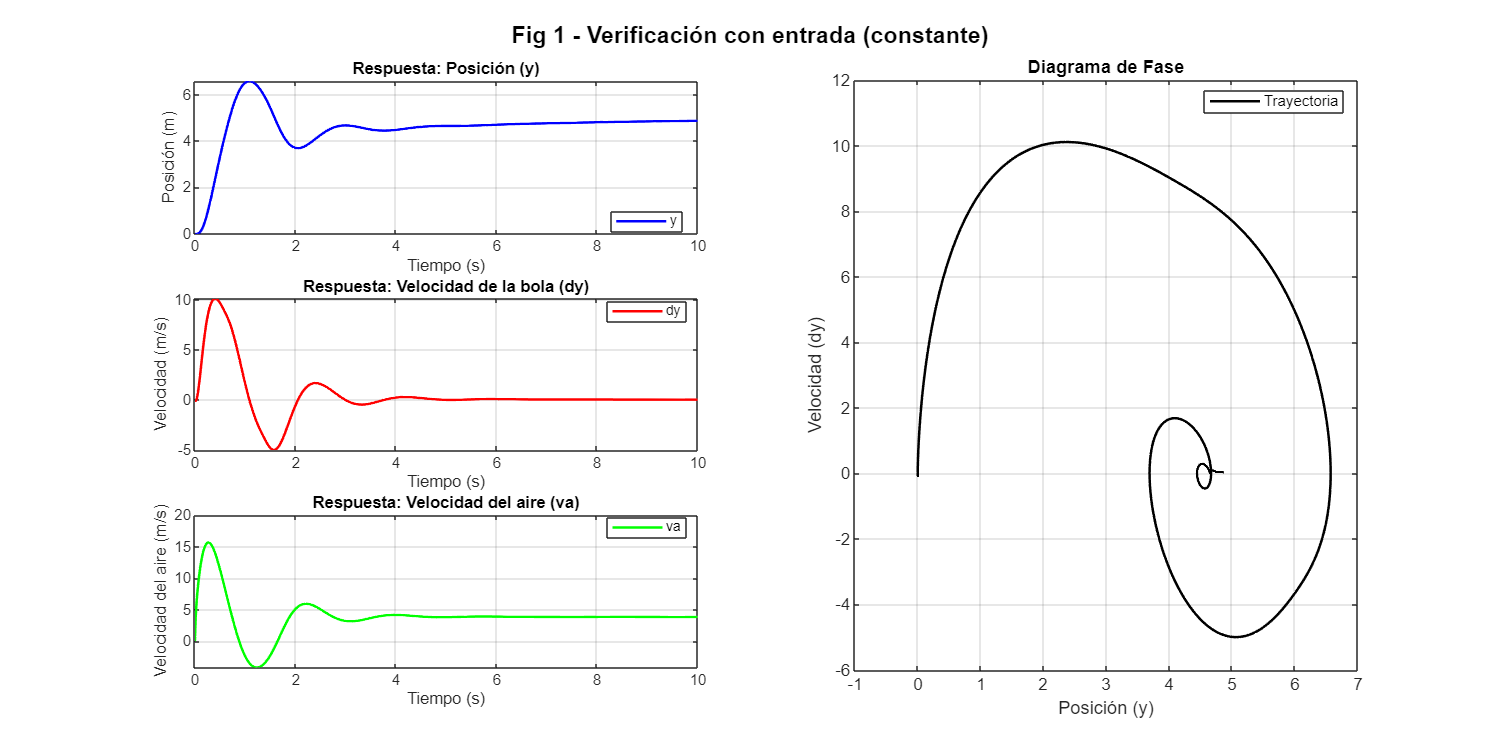

clear all;
close all;
%Tiempo máximo
T = 10;

% Create time vector (e.g., 0 to 10 seconds in 0.1 increments)
Ts = 0.1;
time = 0:Ts:T;


% Create corresponding data vector (example: sine wave)
cs = 5;
data = ones(size(time)) * cs;
% Create timeseries object
u = timeseries(data, time);
%Parámetros
g = 9.81;
m = 3.84 * 10^-3;

A = 5.7 * 10^-3;
Cd = 0.74;
rho = 1.23;

tao1 = 0.14;
kf = 7.78;
alfa = (1/2) * rho * A * Cd;
ci = zeros(1, 3);

kp = 0.5;
ki = 0.1;
kd = 0.01;

%sim = ('Levitador_aire_parametrizado')
set_param('Levitador_aire_parametrizado', 'StopTime', num2str(T));
set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');
sim('Levitador_aire_parametrizado');
% Extraer tiempo
t_plot = y.Time;

figure('Position', [100, 100, 1200, 600]);

% Título global de la figura
sg = sgtitle('Fig 1 - Verificación con entrada (constante)');
sg.FontSize = 14;
sg.FontWeight = 'bold';

% --- Columna Izquierda: 3 subplots verticales ---

% Subplot 1 (fila 1, columna 1): Posición (y) en azul
subplot(3,2,1)
plot(t_plot, y.Data, 'b', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Respuesta: Posición (y)');
legend('y', 'Location', 'best');
grid on;

% Subplot 2 (fila 2, columna 1): Velocidad de la bola (dy) en rojo
subplot(3,2,3)
plot(t_plot, dy.Data, 'r', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
title('Respuesta: Velocidad de la bola (dy)');
legend('dy', 'Location', 'best');
grid on;

% Subplot 3 (fila 3, columna 1): Velocidad del aire (va) en amarillo
subplot(3,2,5)
plot(t_plot, va.Data, 'g', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad del aire (m/s)');
title('Respuesta: Velocidad del aire (va)');
legend('va', 'Location', 'best');
grid on;

% --- Columna Derecha: Diagrama de fase (posición vs. velocidad) ---
% Se unifican las filas 1, 2 y 3 de la columna derecha en un único subplot
subplot(3,2,[2,4,6])
plot(y.Data, dy.Data, 'k', 'LineWidth', 1.5);
xlabel('Posición (y)');
ylabel('Velocidad (dy)');
title('Diagrama de Fase');
legend('Trayectoria', 'Location', 'best');
grid on;

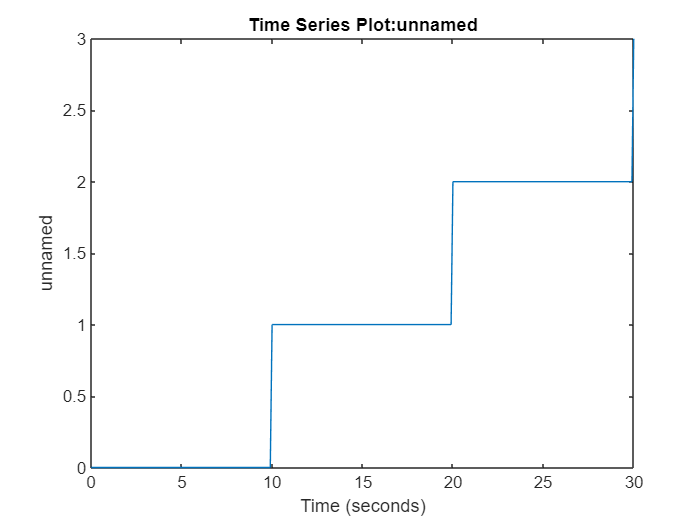

function u_ladd = ladder(T, dt, step_duration, step_size, initial_value)
    % Time vector
    time = 0:dt:T;

    % Number of steps
    num_steps = floor(T / step_duration);

    % Step values
    ladder_values = initial_value + step_size * (0:num_steps);

    % Repeat each value for the duration of a step
    samples_per_step = round(step_duration / dt);
    data = repelem(ladder_values, samples_per_step);

    % Adjust data length to match time vector
    if length(data) > length(time)
        data = data(1:length(time));
    elseif length(data) < length(time)
        data = [data, repmat(data(end), 1, length(time) - length(data))];
    end

    % Create timeseries object
    u_ladd = timeseries(data', time');
end
T = 30;
dt = 0.1;
step_duration = 10;
step_size = 1;
initial_value = 0;

u_ladd = ladder(T, dt, step_duration, step_size, initial_value);
figure;
plot(u_ladd);  % Visualize the signal

#### 3.2.2 Verificación con entrada escalón

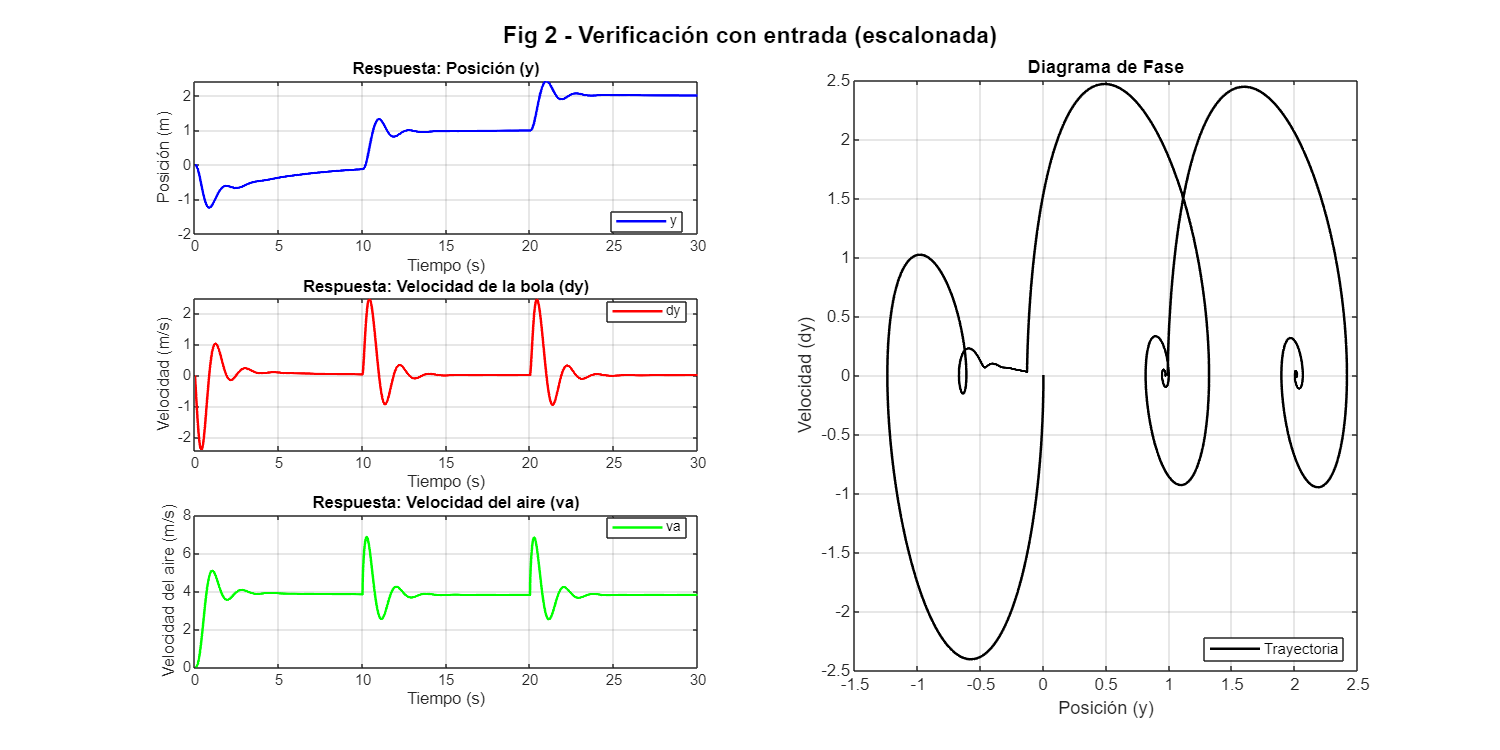

clear all;

%Tiempo máximo
T = 30;

% Create time vector (e.g., 0 to 10 seconds in 0.1 increments)
Ts = 0.1;
time = 0:Ts:T;

% Create corresponding data vector 
dt = 0.1;
step_duration = 10;
step_size = 1;
initial_value = 0;
u_l = ladder(T, dt, step_duration, step_size, initial_value);

u =  timeseries(u_l.Data, time);

%Parámetros
g = 9.81;
m = 3.84 * 10^-3;

A = 5.7 * 10^-3;
Cd = 0.74;
rho = 1.23;

tao1 = 0.14;
kf = 7.78;
alfa = (1/2) * rho * A * Cd;
ci = zeros(1, 3);

kp = 0.5;
ki = 0.1;
kd = 0.01;

set_param('Levitador_aire_parametrizado', 'StopTime', num2str(T));
set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');
sim('Levitador_aire_parametrizado');
t_plot = y.Time;
figure('Position', [100, 100, 1200, 600]);

% Título global de la figura
sg = sgtitle('Fig 2 - Verificación con entrada (escalonada)');
sg.FontSize = 14;
sg.FontWeight = 'bold';

% --- Columna Izquierda: 3 subplots verticales ---

% Subplot 1 (fila 1, columna 1): Posición (y) en azul
subplot(3,2,1)
plot(t_plot, y.Data, 'b', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Respuesta: Posición (y)');
legend('y', 'Location', 'best');
grid on;

% Subplot 2 (fila 2, columna 1): Velocidad de la bola (dy) en rojo
subplot(3,2,3)
plot(t_plot, dy.Data, 'r', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
title('Respuesta: Velocidad de la bola (dy)');
legend('dy', 'Location', 'best');
grid on;

% Subplot 3 (fila 3, columna 1): Velocidad del aire (va) en amarillo
subplot(3,2,5)
plot(t_plot, va.Data, 'g', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad del aire (m/s)');
title('Respuesta: Velocidad del aire (va)');
legend('va', 'Location', 'best');
grid on;

% --- Columna Derecha: Diagrama de fase (posición vs. velocidad) ---
% Se unifican las filas 1, 2 y 3 de la columna derecha en un único subplot
subplot(3,2,[2,4,6])
plot(y.Data, dy.Data, 'k', 'LineWidth', 1.5);
xlabel('Posición (y)');
ylabel('Velocidad (dy)');
title('Diagrama de Fase');
legend('Trayectoria', 'Location', 'best');
grid on;

#### 3.2.3 Verificación con entrada sinusoidal

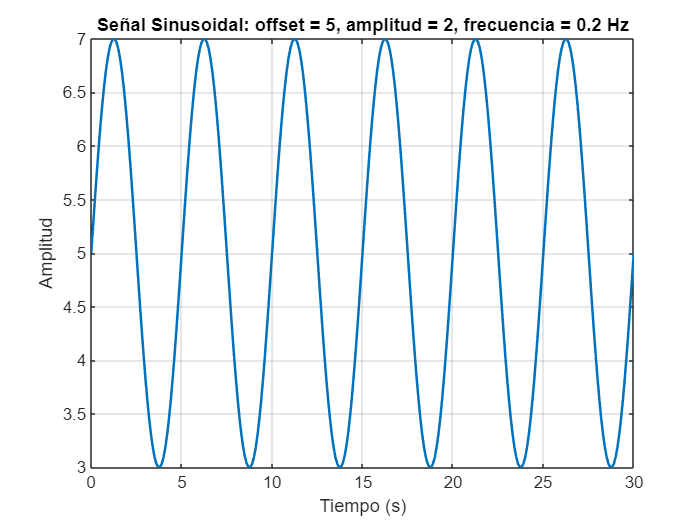

clear all;

% Tiempo máximo
T = 30;

% Crear vector de tiempo
Ts = 0.1;
time = 0:Ts:T;

% Entrada sinusoidal: Por ejemplo, una señal con offset 5 y amplitud 2
% con frecuencia 0.2 Hz (puedes ajustar estos parámetros)
offset = 5;
amplitud = 2;
frecuencia = 0.2;  % Hz
data_sin = offset + amplitud * sin(2*pi*frecuencia*time);

% Graficar la señal
figure;
plot(time, data_sin, 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Señal Sinusoidal: offset = 5, amplitud = 2, frecuencia = 0.2 Hz');
grid on;

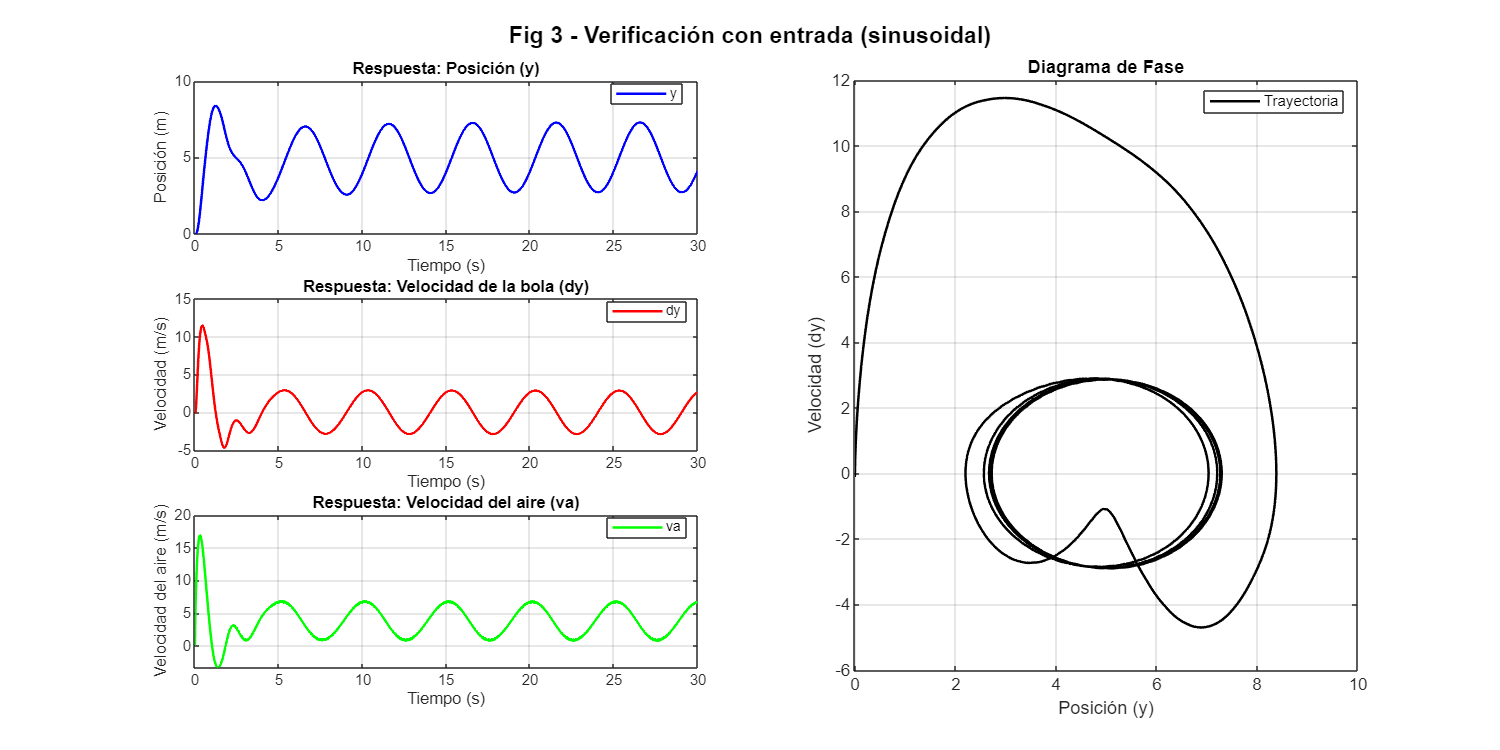



% Crear objeto timeseries para la entrada sinusoidal
u = timeseries(data_sin, time);

% Parámetros del sistema
g = 9.81;
m = 3.84e-3;
A = 5.7e-3;
Cd = 0.74;
rho = 1.23;
tao1 = 0.14;
kf = 7.78;
alfa = (1/2) * rho * A * Cd;
ci = zeros(1, 3);
kp = 0.5;
ki = 0.1;
kd = 0.01;

% Configuración de la simulación
set_param('Levitador_aire_parametrizado', 'StopTime', num2str(T));
set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');

% Ejecutar simulación
sim('Levitador_aire_parametrizado');

% Acceder a las salidas (se asume que los bloques To Workspace guardan en formato Timeseries)
t_plot = y.Time;  % Usando .Time y .Data

figure('Position', [100, 100, 1200, 600]);

% Título global de la figura
sg = sgtitle('Fig 3 - Verificación con entrada (sinusoidal)');
sg.FontSize = 14;
sg.FontWeight = 'bold';

% --- Columna Izquierda: 3 subplots verticales ---

% Subplot 1 (fila 1, columna 1): Posición (y) en azul
subplot(3,2,1)
plot(t_plot, y.Data, 'b', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Respuesta: Posición (y)');
legend('y', 'Location', 'best');
grid on;

% Subplot 2 (fila 2, columna 1): Velocidad de la bola (dy) en rojo
subplot(3,2,3)
plot(t_plot, dy.Data, 'r', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
title('Respuesta: Velocidad de la bola (dy)');
legend('dy', 'Location', 'best');
grid on;

% Subplot 3 (fila 3, columna 1): Velocidad del aire (va) en amarillo
subplot(3,2,5)
plot(t_plot, va.Data, 'g', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad del aire (m/s)');
title('Respuesta: Velocidad del aire (va)');
legend('va', 'Location', 'best');
grid on;

% --- Columna Derecha: Diagrama de fase (posición vs. velocidad) ---
% Se unifican las filas 1, 2 y 3 de la columna derecha en un único subplot
subplot(3,2,[2,4,6])
plot(y.Data, dy.Data, 'k', 'LineWidth', 1.5);
xlabel('Posición (y)');
ylabel('Velocidad (dy)');
title('Diagrama de Fase');
legend('Trayectoria', 'Location', 'best');
grid on;

#### 3.2.4 Verificación con pulso

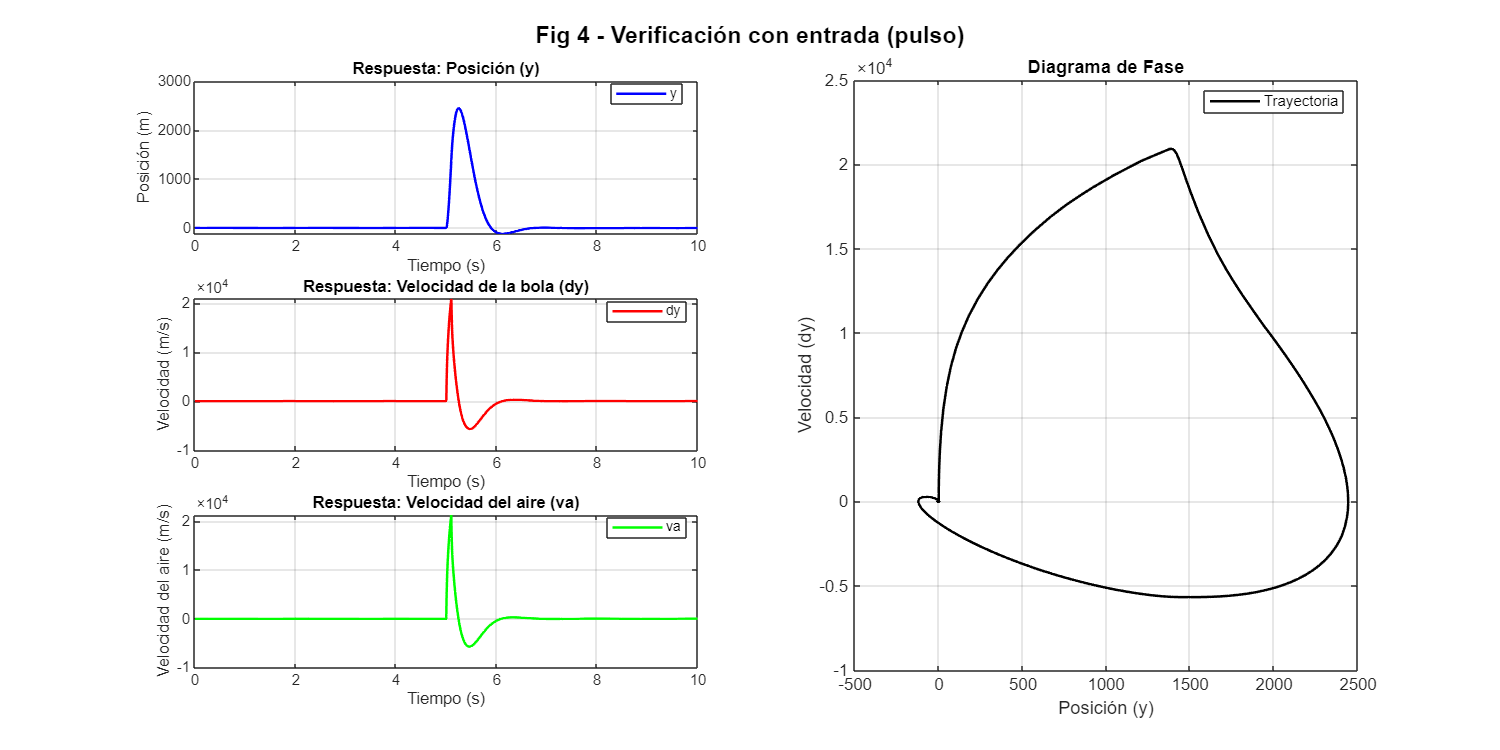

clear all;

% Tiempo máximo
T = 10;

% Crear vector de tiempo
Ts = 0.1;
time = 0:Ts:T;

% Entrada de pulso: Se crea un vector de ceros y se define un pulso en un instante específico.
data_pulse = zeros(size(time));
% Por ejemplo, se activa un pulso en t = 5 s
[~, idx] = min(abs(time-5));  % Buscar el índice más cercano a t = 5
data_pulse(idx) = 10000;  % Definir un pulso grande (puedes ajustar el valor)

% Crear objeto timeseries para la entrada de pulso
u = timeseries(data_pulse, time);

% Parámetros del sistema
g = 9.81;
m = 3.84e-3;
A = 5.7e-3;
Cd = 0.74;
rho = 1.23;
tao1 = 0.14;
kf = 7.78;
alfa = (1/2) * rho * A * Cd;
ci = zeros(1, 3);
kp = 0.5;
ki = 0.1;
kd = 0.01;

% Configuración de la simulación
set_param('Levitador_aire_parametrizado', 'StopTime', num2str(T));
set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');

% Ejecutar simulación
sim('Levitador_aire_parametrizado');

% Acceder a las salidas (formato Timeseries)
t_plot = y.Time;
y1 = y.Data;
y2 = dy.Data;
y3 = va.Data;

figure('Position', [100, 100, 1200, 600]);

% Título global de la figura
sg = sgtitle('Fig 4 - Verificación con entrada (pulso)');
sg.FontSize = 14;
sg.FontWeight = 'bold';

% --- Columna Izquierda: 3 subplots verticales ---

% Subplot 1 (fila 1, columna 1): Posición (y) en azul
subplot(3,2,1)
plot(t_plot, y.Data, 'b', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Respuesta: Posición (y)');
legend('y', 'Location', 'best');
grid on;

% Subplot 2 (fila 2, columna 1): Velocidad de la bola (dy) en rojo
subplot(3,2,3)
plot(t_plot, dy.Data, 'r', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad (m/s)');
title('Respuesta: Velocidad de la bola (dy)');
legend('dy', 'Location', 'best');
grid on;

% Subplot 3 (fila 3, columna 1): Velocidad del aire (va) en amarillo
subplot(3,2,5)
plot(t_plot, va.Data, 'g', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad del aire (m/s)');
title('Respuesta: Velocidad del aire (va)');
legend('va', 'Location', 'best');
grid on;

% --- Columna Derecha: Diagrama de fase (posición vs. velocidad) ---
% Se unifican las filas 1, 2 y 3 de la columna derecha en un único subplot
subplot(3,2,[2,4,6])
plot(y.Data, dy.Data, 'k', 'LineWidth', 1.5);
xlabel('Posición (y)');
ylabel('Velocidad (dy)');
title('Diagrama de Fase');
legend('Trayectoria', 'Location', 'best');
grid on;

### 3.3 Variación de los parámetros

#### 3.3.1 Variación de la constante de masa de la bola

clear all;

% Valores a probar para la masa de la bola (m) [en kg]
%m_values = linspace(0.001, 0.03, 5);  % Por ejemplo, 5 valores desde 0.001 hasta 0.01 kg
m_values = logspace(log10(0.001), log10(0.03), 5);

m_values =     0.0010    0.0023    0.0055    0.0128    0.0300


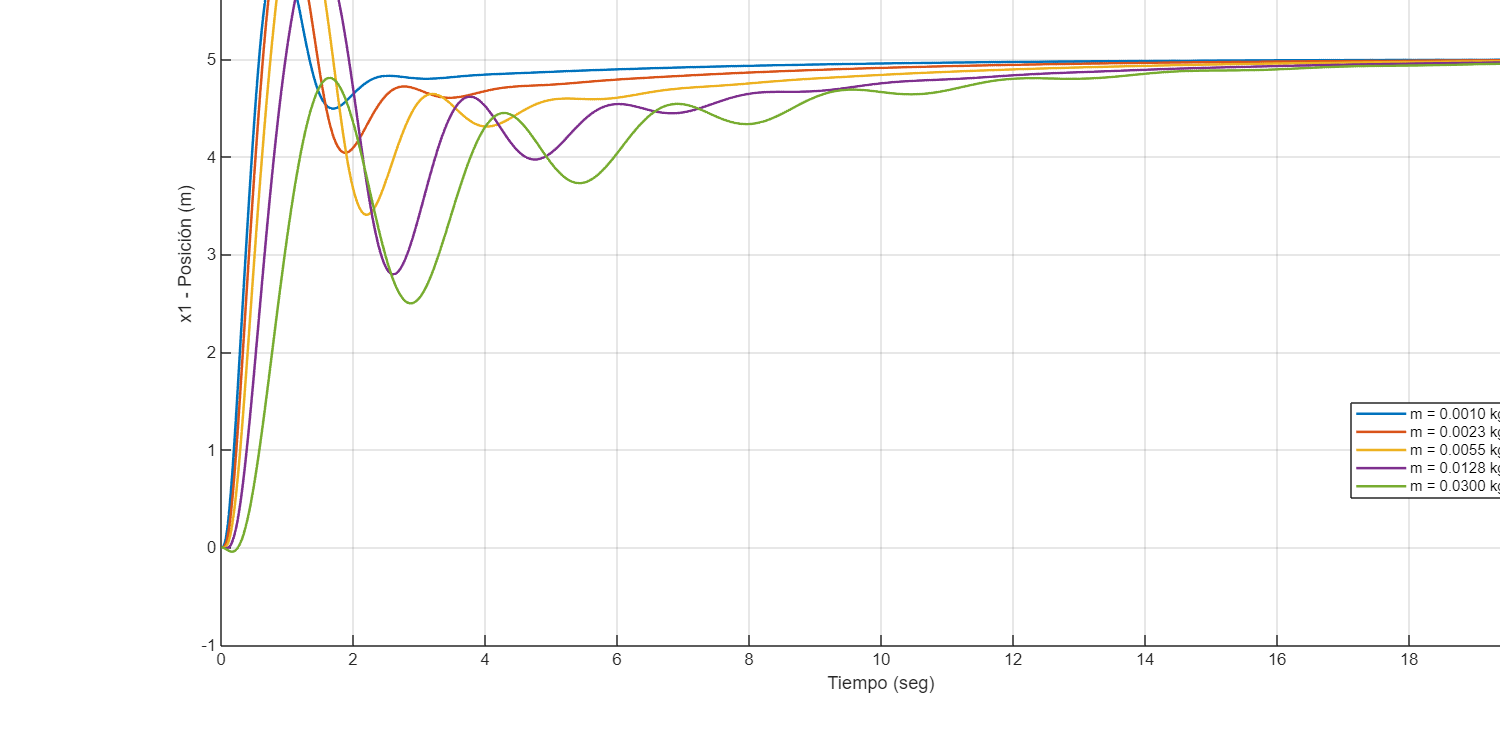


% Prepara la figura para los gráficos
figure('Units','normalized','Position',[0 0 1 1])
hold on
grid on
sgtitle({'Fig 5 - Respuesta temporal con variación de la masa (m)'; ''})
xlabel('Tiempo (seg)')
ylabel('x1 - Posición (m)')

% Inicializar arrays para guardar características de la respuesta temporal
stabilization_times = zeros(1, length(m_values));
stabilization_values = zeros(1, length(m_values));
max_peaks = zeros(1, length(m_values));
overimpulse_values = zeros(1, length(m_values));

% Bucle para simular y graficar para cada valor de m
for i = 1:length(m_values)
    colors = lines(length(m_values));  % Genera un conjunto de colores para diferenciar las curvas
    m_val = m_values(i);  % Valor actual de la masa

    g = 9.81;
    m = m_val;
    A = 5.7e-3;
    Cd = 0.74;
    rho = 1.23;
    tao1 = 0.14;
    kf = 7.78;
    alfa = (1/2) * rho * A * Cd;
    ci = zeros(1, 3);
    kp = 0.5;
    ki = 0.1;
    kd = 0.01;   
    
    % Tiempo de simulación
    tmax = 20;
    Ts = 0.1;
    time = 0:Ts:tmax;
       
    % Create corresponding data vector (example: sine wave)
    cs = 5;
    data = ones(size(time)) * cs;
    % Create timeseries object
    u = timeseries(data, time);   
    
    % Configuración de la simulación
    set_param('Levitador_aire_parametrizado', 'StopTime', num2str(tmax));
    set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');
    
    % Ejecutar simulación
    sim('Levitador_aire_parametrizado');

    % Extraer resultados de la simulación: se asume que la posición está en la primera columna
    t_sim = y.Time;
    y1 = y.Data;
    
    % Graficar la respuesta para este valor de m
    plot(t_sim, y1, 'Color', colors(i,:), 'LineWidth', 1.5)

    % Calcular valores escalares usando la función stepinfo
    info = stepinfo(y1, t_sim);
    stabilization_times(i) = info.SettlingTime;  % Tiempo de estabilización
    stabilization_values(i) = mean(y1(end-100:end));  % Valor de estabilización (promedio de los últimos 100 puntos)
    max_peaks(i) = max(y1);  % Pico máximo
    overimpulse_values(i) = max(y1) - mean(y1(end-100:end));  % Valor de sobreimpulso
end
% Añadir leyenda para identificar cada curva
legend_entries = arrayfun(@(m_val) sprintf('m = %.4f kg', m_val), m_values, 'UniformOutput', false);
legend(legend_entries, 'Location', 'best')
hold off

% Crear y mostrar la tabla de resultados
tabla = [m_values' stabilization_times' stabilization_values' max_peaks' overimpulse_values'];
disp('Tabla de resultados (m, Tiempos de Estabilización, Valores de Estabilización, Valores Máximos, Valor de Sobreimpulso):')

Tabla de resultados (m, Tiempos de Estabilización, Valores de Estabilización, Valores Máximos, Valor de Sobreimpulso):


disp(tabla)

    0.0010    6.0005    4.9940    6.1079    1.1139
    0.0023    9.0403    4.9879    6.4197    1.4318
    0.0055   11.4457    4.9783    6.6237    1.6454
    0.0128   13.1886    4.9658    6.1659    1.2001
    0.0300   14.1562    4.9532    4.9583    0.0050



#### 3.3.2 Variación de la constante de resistencia del aire

clear all;

% Valores a probar para la resistencia del aire (Cd)
%Cd_values = linspace(0.5, 5, 5);  % 5 valores entre 0.5 y 5
Cd_values = logspace(log10(0.5), log10(5), 5);

Cd_values =     0.5000    0.8891    1.5811    2.8117    5.0000


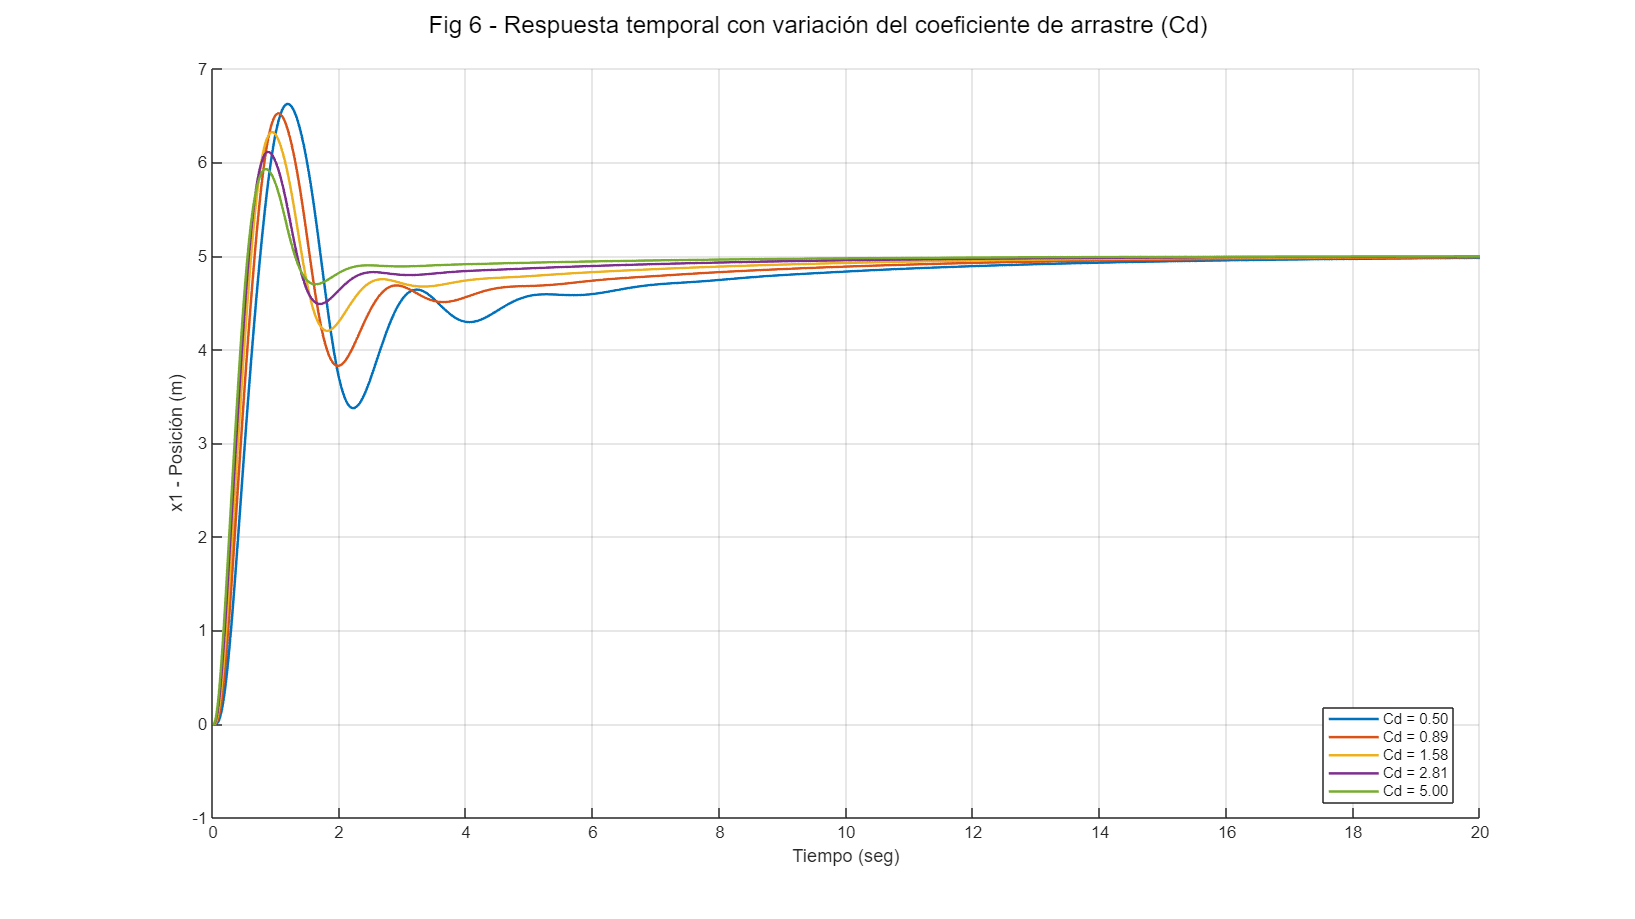


% Prepara la figura para los gráficos
figure('Units','normalized','Position',[0 0 1 1])
hold on
grid on
sgtitle({'Fig 6 - Respuesta temporal con variación del coeficiente de arrastre (Cd)'; ''})
xlabel('Tiempo (seg)')
ylabel('x1 - Posición (m)')

% Inicializar arrays para guardar características de la respuesta temporal
stabilization_times = zeros(1, length(Cd_values));
stabilization_values = zeros(1, length(Cd_values));
max_peaks = zeros(1, length(Cd_values));
overimpulse_values = zeros(1, length(Cd_values));

% Bucle para simular y graficar para cada valor de Cd
for i = 1:length(Cd_values)
    colors = lines(length(Cd_values));  % Genera colores para diferenciar las curvas
    cd_val = Cd_values(i);  % Valor actual de Cd

    % Parámetros constantes
    g = 9.81;
    m = 3.84e-3;    
    A = 5.7e-3;
    Cd = cd_val;           % Actualizamos Cd con el valor actual
    rho = 1.23;
    tao1 = 0.14;
    kf = 7.78;
    alfa = 0.5 * rho * A * Cd;
    ci = zeros(1, 3);
    kp = 0.5;
    ki = 0.1;
    kd = 0.01;   
    
    % Tiempo de simulación
    tmax = 20;
    Ts = 0.1;
    time = 0:Ts:tmax;
       
    % Crear vector de entrada (constante)
    cs = 5;
    data = ones(size(time)) * cs;
    % Crear objeto timeseries para la entrada
    u = timeseries(data, time);   
    
    % Configuración de la simulación
    set_param('Levitador_aire_parametrizado', 'StopTime', num2str(tmax));
    set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');
    
    % Ejecutar simulación
    sim('Levitador_aire_parametrizado');

    % Extraer resultados de la simulación (se asume que la salida de posición se guarda en 'y')
    t_sim = y.Time;
    x1 = y.Data;
    
    % Graficar la respuesta para este valor de Cd
    plot(t_sim, x1, 'Color', colors(i,:), 'LineWidth', 1.5)

    % Calcular valores escalares usando la función stepinfo
    info = stepinfo(x1, t_sim);
    stabilization_times(i) = info.SettlingTime;  % Tiempo de estabilización
    stabilization_values(i) = mean(x1(end-100:end));  % Valor de estabilización (promedio de los últimos 100 puntos)
    max_peaks(i) = max(x1);  % Pico máximo
    overimpulse_values(i) = max(x1) - mean(x1(end-100:end));  % Valor de sobreimpulso
end

% Añadir leyenda para identificar cada curva (se muestra el valor de Cd)
legend_entries = arrayfun(@(cd_val) sprintf('Cd = %.2f', cd_val), Cd_values, 'UniformOutput', false);
legend(legend_entries, 'Location', 'best')
hold off

% Crear y mostrar la tabla de resultados
tabla = [Cd_values' stabilization_times' stabilization_values' max_peaks' overimpulse_values'];
disp('Tabla de resultados (Cd, Tiempos de Estabilización, Valores de Estabilización, Valores Máximos, Valor de Sobreimpulso):')

Tabla de resultados (Cd, Tiempos de Estabilización, Valores de Estabilización, Valores Máximos, Valor de Sobreimpulso):


disp(tabla)

    0.5000   11.5386    4.9778    6.6242    1.6465
    0.8891    9.9798    4.9849    6.5232    1.5384
    1.5811    8.1819    4.9901    6.3226    1.3325
    2.8117    6.0445    4.9939    6.1116    1.1177
    5.0000    3.3851    4.9967    5.9286    0.9319



#### 3.3.3 **Variación de la constante de ganancia del ventilador**

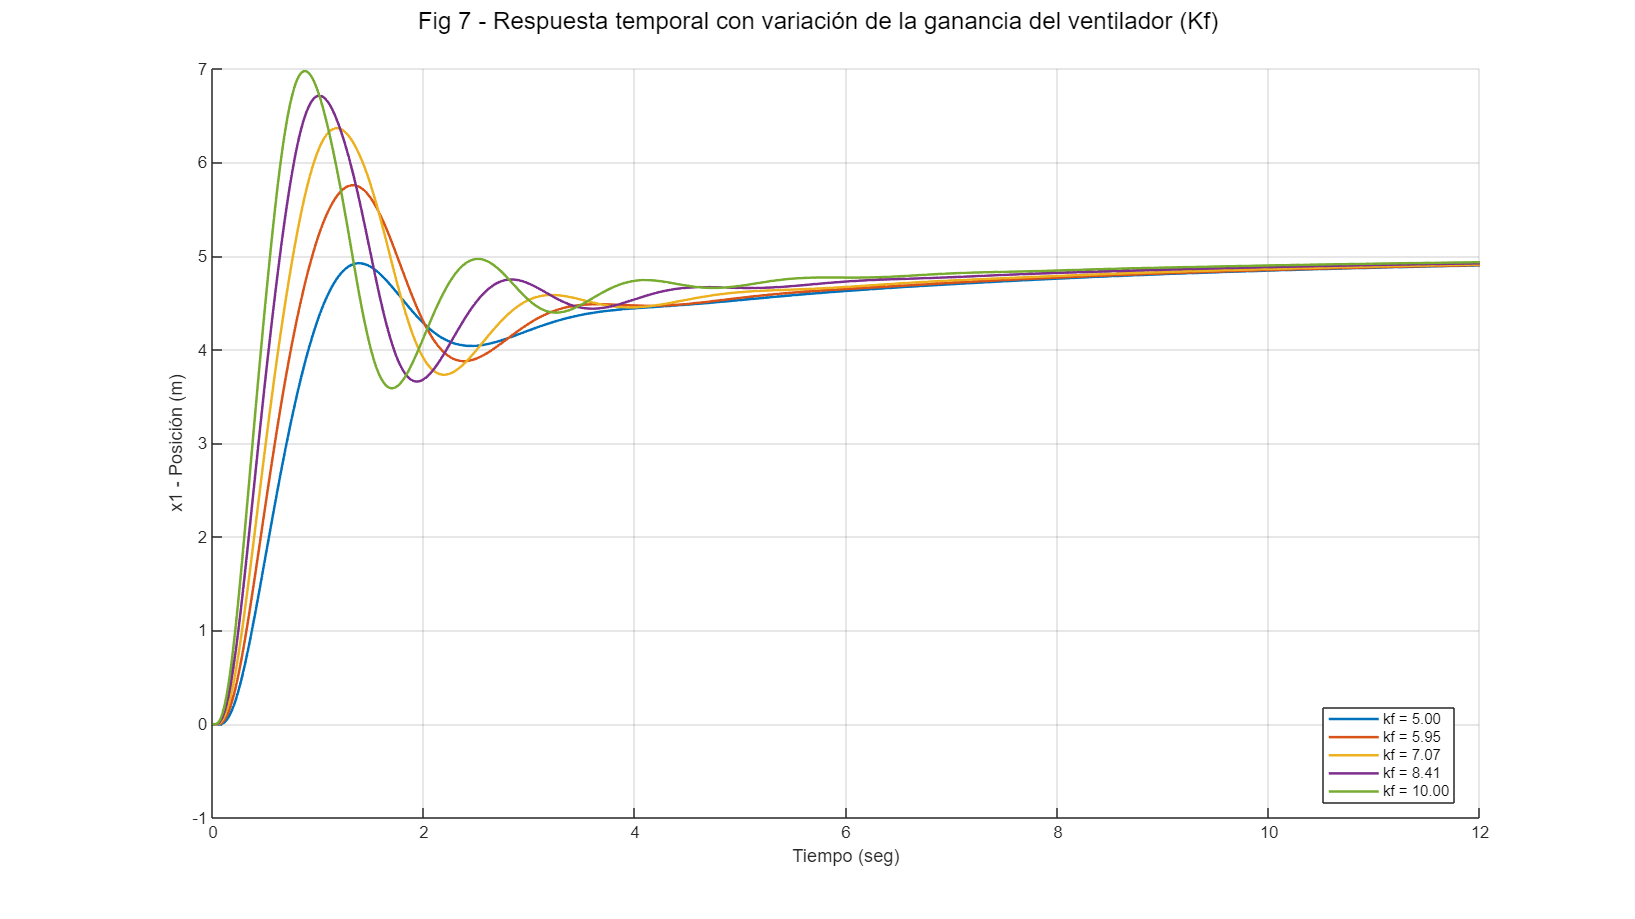

clear all;

% Valores a probar para la ganancia del ventilador (kf)
%kf_values = linspace(5, 10, 5);  % Por ejemplo, 5 valores desde 5 hasta 10
kf_values = logspace(log10(5), log10(10), 5);

% Prepara la figura para los gráficos
figure('Units','normalized','Position',[0 0 1 1])
hold on
grid on
sgtitle({'Fig 7 - Respuesta temporal con variación de la ganancia del ventilador (Kf)'; ''})
xlabel('Tiempo (seg)')
ylabel('x1 - Posición (m)')

% Inicializar arrays para guardar características de la respuesta temporal
stabilization_times = zeros(1, length(kf_values));
stabilization_values = zeros(1, length(kf_values));
max_peaks = zeros(1, length(kf_values));
overimpulse_values = zeros(1, length(kf_values));

% Bucle para simular y graficar para cada valor de kf
for i = 1:length(kf_values)
    colors = lines(length(kf_values));  % Genera un conjunto de colores para diferenciar las curvas
    kf_val = kf_values(i);  % Valor actual de kf

    % Parámetros constantes
    g = 9.81;
    m = 3.84e-3;        
    A = 5.7e-3;
    Cd = 0.74;       
    rho = 1.23;
    tao1 = 0.14;
    kf = kf_val;         % Actualiza la ganancia del ventilador
    alfa = 0.5 * rho * A * Cd;
    ci = zeros(1, 3);
    kp = 0.5;
    ki = 0.1;
    kd = 0.01;   
    
    % Tiempo de simulación
    tmax = 12;
    Ts = 0.1;
    time = 0:Ts:tmax;
       
    % Crear vector de entrada (constante)
    cs = 5;
    data = cs * ones(size(time));
    % Crear objeto timeseries para la entrada
    u = timeseries(data, time);   
    
    % Configuración de la simulación
    set_param('Levitador_aire_parametrizado', 'StopTime', num2str(tmax));
    set_param('Levitador_aire_parametrizado', 'MaxStep', '0.01');
    
    % Ejecutar simulación
    sim('Levitador_aire_parametrizado');
    
    % Extraer resultados de la simulación: se asume que la posición está en la primera columna
    t_sim = y.Time;
    x1 = y.Data;
    
    % Graficar la respuesta para este valor de kf
    plot(t_sim, x1, 'Color', colors(i,:), 'LineWidth', 1.5)
    
    % Calcular características de la respuesta usando stepinfo
    info = stepinfo(x1, t_sim);
    stabilization_times(i) = info.SettlingTime;                % Tiempo de estabilización
    stabilization_values(i) = mean(x1(end-100:end));           % Valor de estabilización (promedio de los últimos 100 puntos)
    max_peaks(i) = max(x1);                                    % Pico máximo
    overimpulse_values(i) = max(x1) - mean(x1(end-100:end));    % Valor de sobreimpulso
end

% Añadir leyenda para identificar cada curva (mostrando el valor de kf)
legend_entries = arrayfun(@(kf_val) sprintf('kf = %.2f', kf_val), kf_values, 'UniformOutput', false);
legend(legend_entries, 'Location', 'best')
hold off

% Crear y mostrar la tabla de resultados
tabla = [kf_values' stabilization_times' stabilization_values' max_peaks' overimpulse_values'];
disp('Tabla de resultados (kf, Tiempos de Estabilización, Valores de Estabilización, Valores Máximos, Valor de Sobreimpulso):')

Tabla de resultados (kf, Tiempos de Estabilización, Valores de Estabilización, Valores Máximos, Valor de Sobreimpulso):


disp(tabla)

    5.0000    8.8934    4.8874    4.9227    0.0353
    5.9460    8.7710    4.8912    5.7559    0.8647
    7.0711    8.5510    4.8989    6.3657    1.4668
    8.4090    8.1136    4.9131    6.7125    1.7994
   10.0000    7.6626    4.9262    6.9750    2.0489



## 4. Discusión

## **Referencias**